# Testing Digital Output

## Clear Workspace

close all; clearvars; clc;

## Set Variable

outputRate = 1e6; % Sets the rate that the NI-Board output at
bufferForPreLoad = 500e3; % sets the length of buffer for preloading
pkpV = 1; % pk-pk voltage per frequency
f1 = 75e3; % lowest frequency component Hz
f2 = 100e3; % mid frequency component Hz
f3 = 125e3; % highest frequency component Hz
phase = pi; % phase of second signal
skipNum = 1; % number of electrods to skip
numChannels = 16; % number of channels in system

## Connect to NI-Boards

dDOut = daq("ni");
digitalCh1 = addoutput(dDOut, "Dev1", "port1/line0:4","Digital"); % adds the digital data lines for board 1

digitalCh2 = addoutput(dDOut, "Dev2", "port1/line0:4", "Digital"); % adds the digital data lines for board 2

dAnalog = daq("ni"); % Initialize connection to the NI-Board for analog output
addoutput(dAnalog,"Dev1","ao0","Voltage"); % Adds an analog output
addoutput(dAnalog,"Dev2","ao0","Voltage"); % Adds an analog output
dAnalog.Rate = outputRate; % sets the output sampling rate Hz

outputSignal = [createSine(pkpV/2, f1, f2, f3, 0, outputRate, "bipolar", bufferForPreLoad) createSine(pkpV/2, f1, f2, f3, phase, outputRate, "bipolar", bufferForPreLoad)]; % calls function to generate wave vector

preload(dAnalog,outputSignal); % loads wave vector into NI-Board

## Start Output

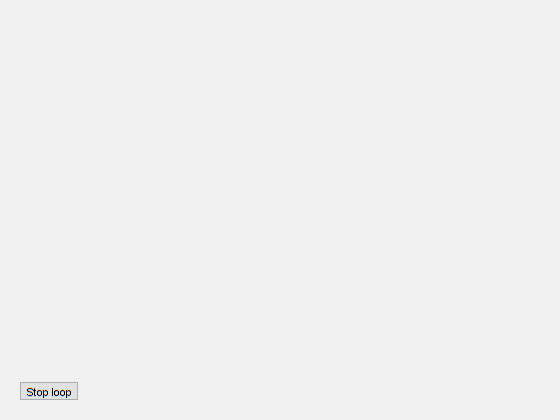

ButtonHandle = uicontrol('Style', 'PushButton', ...
                         'String', 'Stop loop', ...
                         'Callback', 'delete(gcbf)');

start(dAnalog,"repeatoutput") % starts wave output from the NI-Board
while true
    for i = 0:1:1
        setMux(dDOut, i, skipNum, numChannels)
        pause(0.5);
    end
    if ~ishandle(ButtonHandle)
        disp('Loop stopped by user');
        break;
    end
end

## Stop Output

write(dDOut, [0 0 0 0 0 0 0 0 0 0]);
stop(dAnalog)

## Sine Function

function sine = createSine(A, frq1, frq2, frq3, phase, sampleRate, type, bufferForPreLoad)
    timeStep = 1/sampleRate; % period of the sampling frequency
    periods = 1/eval(gcd(sym([frq1 frq2 frq3]))); % calculates the length of the period for a periodic
    t = (0:timeStep:periods-timeStep)'; % calculates the time vector from the period
        if type == "bipolar"
            y = A*sin(2*pi*frq1*t+phase) + A*sin(2*pi*frq2*t+phase) + A*sin(2*pi*frq3*t+phase); % calculates the signal along the time vector
        elseif type == "unipolar"
            y = A*sin(2*pi*frq1*t+phase) + A*sin(2*pi*frq2*t+phase) + A*sin(2*pi*frq3*t+phase) + A; % calculates the signal along the time vector
        end
    numCycles = ceil(bufferForPreLoad/(periods/timeStep)); % calculate the number of cycles to make a full buffer for preloading
    sine = repmat(y, numCycles, 1); % extends the data vector to match or execed the buffer length
end

## Mux Function

function setMux(device, currentInjection, skipNum, numChannels)
    output = [1, str2double(num2cell(dec2bin(mod(currentInjection, numChannels), 4))), 1, str2double(num2cell(dec2bin(mod(currentInjection + skipNum, numChannels), 4)))];
    write(device, output);
end